clear all
clc

load GP2  %輸入的答案
load EsT  %散射場


GP = GP2; 

% =============提取實部資料=============
EsT = real(EsT);

% ===============旋轉90度==============
GP = reshape(GP,[32,32,1200,1]);
GP_rot90 = rot90(GP);
GP_rot180 = rot90(GP_rot90);
GP_rot270 = rot90(GP_rot180);
% ===============上下左右翻轉==============
GP_rotrf = fliplr(GP);
GP_rotud = flipud(GP);
% =================合併================
real_GP = cat(4,GP,GP_rot90,GP_rot180,GP_rot270,GP_rotrf,GP_rotud);


% ===============旋轉90度==============
EsT = real(EsT);
EsT = reshape(EsT,[32,32,1200,1]);
EsT_90 = rot90(EsT);
EsT_180 = rot90(EsT_90);
EsT_270 = rot90(EsT_180);
% ===============上下左右翻轉==============
EsT_rotlr = fliplr(EsT);
EsT_rotud = flipud(EsT);
% =================合併================
real_EsT = cat(4,EsT,EsT_90,EsT_180,EsT_270,EsT_rotlr,EsT_rotud);

%====================================

real_GP= reshape(real_GP,[32,32,1,7200]);
real_EsT= reshape(real_EsT,[32,32,1,7200]);

[size1,size2,channel,data_number]=size(real_GP);

F = randperm(data_number); 

for x=1:data_number
    
   
    real_GP(:,:,:,x)= real_GP(:,:,:,F(x)); 
    
    real_EsT(:,:,:,x)= real_EsT(:,:,:,F(x)); 

end


number_train = data_number*0.8;  % 提取训练和验证数据 80% 训练，20% 验证

real_GP_Training = (real_GP(:,:,1,1:number_train)); %training的答案
real_EsT_Training = (real_EsT(:,:,1,1:number_train)); %training的資料
real_GP_Testing = (real_GP(:,:,1,number_train+1:data_number)); %test的答案
real_EsT_Testing = (real_EsT(:,:,1,number_train+1:data_number)); %test的資料

test_GP = real_GP_Testing;

save test_GP test_GP



# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-Sep-2021 13:41:35

## Create Array of Layers

layers = [
    imageInputLayer([32 32 1],"Name","imageinput")
    convolution2dLayer([3 1],20,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 1],40,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    convolution2dLayer([2 2],80,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(1024,"Name","fc")
    chiuout("sam")
    regressionLayer("Name","regressionoutput")];


## Plot Layers

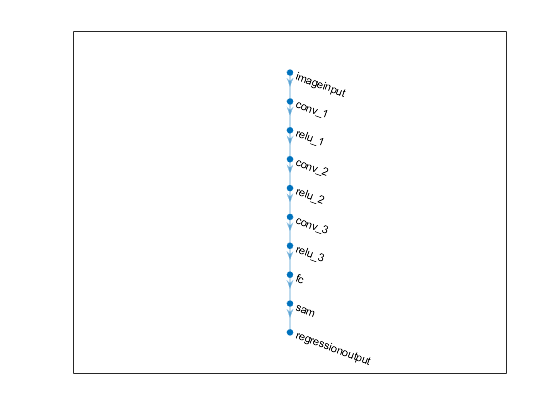

plot(layerGraph(layers));



options = trainingOptions('adam', ...
    'LearnRateSchedule','piecewise', ...
    "InitialLearnRate",1.0e-4, ...
    'LearnRateDropFactor',0.1, ...
    'L2Regularization',1.0000e-4,...
    'LearnRateDropPeriod',100, ...
    'MaxEpochs',200, ...
    'MiniBatchSize',16, ...
    'Shuffle',"every-epoch",...
    'Plots','training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 100
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 200
                   MiniBatchSize: 16
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                   

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:11 |        35.77 |        639.8 |      1.0000e-04 |
|       1 |          50 |       00:00:17 |         6.58 |         21.6 |      1.0000e-04 |
|       1 |         100 |       00:00:22 |         4.88 |         11.9 |      1.0000e-04 |
|       1 |         150 |       00:00:27 |         5.38 |         14.5 |      1.0000e-04 |
|       1 |         200 |       00:00:32 |         5.12 |         13.1 |      1.0000e-04 |
|       1 |         250 |       00:00:37 |         5.04 |         12.7 |      1.0000e-04 |
|       1 |         300 |  

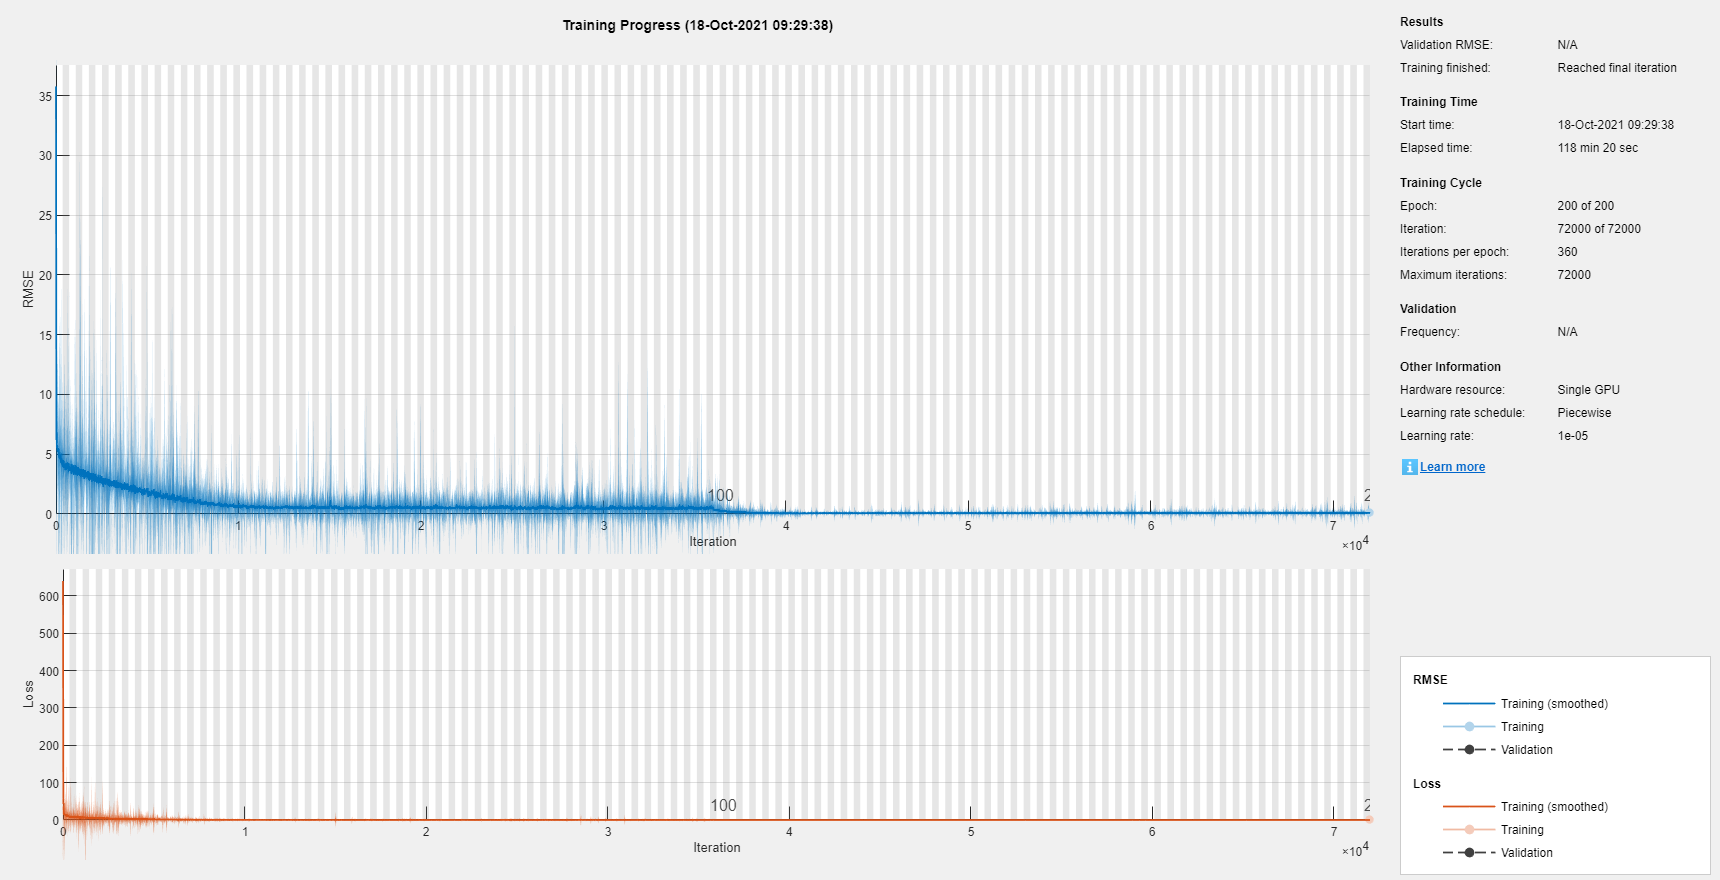

net =   SeriesNetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}




% options = trainingOptions('sgdm', ...
%     'Momentum', 0.99, ...
%     'LearnRateSchedule','piecewise', ...
%     "InitialLearnRate",1.0e-4, ...
%     'LearnRateDropFactor',0.1, ...
%     'L2Regularization',1.0000e-4,...
%     'LearnRateDropPeriod',100, ...
%     'MaxEpochs',200, ...
%     'MiniBatchSize',16, ...
%     'Shuffle',"every-epoch",...
%     'Plots','training-progress')
 

net = trainNetwork(real_EsT_Training,real_GP_Training,layers,options)


test_EsT = predict(net,real_EsT_Testing);

save test_EsT test_EsT


